clear all; close all;
%--------------- 4 ----------------%
x1 = [0,1,2,3,3,2,1,0];
x2 = [0,7,0,2,0,2,0,7,4,2];
x3 = [0,0,0,0,0,0,0,15];

ile1 = liczbabitow(x1); % bit/symbol
ile2 = liczbabitow(x2); % bit/symbol
ile3 = liczbabitow(x3); % bit/symbol
disp([num2str(ile1), ' bit/symbol dla x1.']);

2 bit/symbol dla x1.


disp([num2str(ile2), ' bit/symbol dla x2.']);

1.8464 bit/symbol dla x2.


disp([num2str(ile3), ' bit/symbol dla x3.']);

0.54356 bit/symbol dla x3.



%--------------- 5 ----------------%
%kodx2 = [0'110'0'10'0'10'0'110'111'10]
znaki = [4,7,2,0];
bity = [111,110,10,0];
M = containers.Map(znaki,bity);
kodx2 =[];
codestrx2='';
for i = 1:length(x2)
    znak = x2(i);
    kodx2 = [kodx2, M(znak)];
    s = num2str(M(znak));
    codestrx2 = strcat(codestrx2,s);
end


rng(0);
x4 = randi([1 5],1,10);
x4 = [5,5,1,5,4,1,2,3,5,5];
x1=x4;
p = unique(x1);
ile = zeros(length(p),1);
x = sort(x1);
for j = 1:length(p)
    for i = 1:length(x)
        if x(i) == p(j)
            ile(j) = ile(j)+1;
        end
    end
end
for n =1:length(ile)
    prob(n) = ile(n)/length(x1);
end

%koder
znaki = [2,3,4,1,5];
bity = [1111,1110,110,10,0];
Mkoder = containers.Map(znaki,bity);
kodx4 =[];
codestrx4='';
for i = 1:length(x4)
    znak = x4(i);
    kodx4 = [kodx4, Mkoder(znak)];
    s = num2str(Mkoder(znak));
    codestrx4 = strcat(codestrx4,s);
end
ileEntropia = length(x4)*liczbabitow(x4);
ileHuffman = length(codestrx4);
disp([num2str(ileEntropia), ' bitów minimum (entropia) x4.']);

19.6096 bitów minimum (entropia) x4.


disp([num2str(ileHuffman), ' bitów Huffman x4.']);

20 bitów Huffman x4.


%dekoder
Mdekoder = containers.Map(bity,znaki);
datax4 =[];
for i = 1:length(kodx4)
    znak = kodx4(i);
    datax4 = [datax4, Mdekoder(znak)];
end

%--------------- opcjonalne ----------------%
% koder
clear;

fileID = fopen('lab11.txt','r');
formatSpec = '%f';
A = fscanf(fileID,formatSpec);
fclose(fileID);
x4 = A';

x4 = [5,5,1,5,4,1,2,3,5,5];
A = x4';

L = length(x4);
x = x4;
p = unique(x);
ile = zeros(length(p),1);
x = sort(x);
for j = 1:length(p)
    for i = 1:L
        if x(i) == p(j)
            ile(j) = ile(j)+1;
        end
    end
end
for n =1:length(ile)
    prob(n) = ile(n)/L;
end

distinctVal = p;
[probSorted, probIndex] = sort(prob);
sortedDistinct = zeros(1,length(distinctVal));
for n = 1:length(distinctVal)
    index = probIndex(n);
    sortedDistinct(n) = distinctVal(index);
end

%wiki

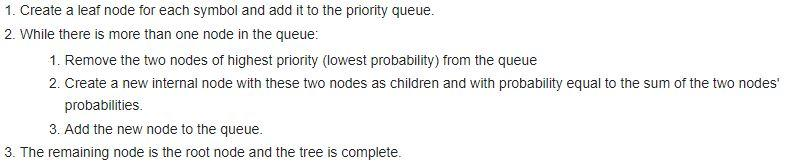

for i = 1:length(sortedDistinct)
    node.probab = probSorted(i);
    node.value = sortedDistinct(i);
    node.lewy =[];
    node.prawy =[];
    kolejka(i) = node;
end

while(length(kolejka)>1)
    newNode.lewy = kolejka(1);
    newNode.prawy = kolejka(2);
    newNode.probab = kolejka(1).probab + kolejka(2).probab;
    newNode.value = [];    
    kolejka(1:2) = [];
    kolejka = [newNode,kolejka];
end

s = tablicaKodera([],kolejka);  % dana funkcja

bity=[];
wartosci = [];
for n = 1:length(s)
    bity = [bity,str2double(s(n).bits)];
    wartosci = [wartosci,s(n).value];
end


%koder
Mkoder = containers.Map(wartosci,bity);
kod =[];
codestrx4='';
for i = 1:length(x4)
    znak = x4(i);
    kod = [kod, Mkoder(znak)];
    s = num2str(Mkoder(znak));
    codestrx4 = strcat(codestrx4,s);
end
if(1)
k=1;
s=1;
newcode=[];
for n=1:length(codestrx4)
    if(codestrx4(n)=='0')
        newcode(s) = str2double(codestrx4(k:n));
        k=n;
        s=s+1;
    end
end

%newcode = kod;
ilewiecej = 0;
for n=1:length(newcode)
    if(newcode(n)>max(bity))
        ilewiecej =ilewiecej+1;
    end
end

if(ilewiecej>0)
    for n=1:length(newcode)+ilewiecej
        if(newcode(n)>max(bity))
            zamiana = [];
            tmp = num2str(newcode(n));
            ile = length(num2str(max(bity)));
            while(length(tmp)>ile)
                tmp = tmp(ile+1:end);
                zamiana = [zamiana,max(bity)];
            end
            if n==1
                wynik = [zamiana,str2double(tmp),newcode(n+1:end)];
                newcode = wynik;
            elseif n==length(newcode)
                wynik = [newcode(1:n-1),zamiana,str2double(tmp)];
                newcode = wynik;
            else
                wynik = [newcode(1:n-1),zamiana,str2double(tmp),newcode(n+1:end)];    
                newcode = wynik;
            end
        end
    end
    kod = wynik;
end
end


%dekoder
Mdekoder = containers.Map(bity,wartosci);
data =[];
for i = 1:length(kod)
    znak = kod(i);
    data = [data, Mdekoder(znak)];
end

%czy się udało
wejscie = A';
wyjscie = data;
figure;
plot(abs(wejscie - wyjscie));
title("błąd po dekodowaniu");

